clear;clc;close all;

% Stage 0 Solar physics
kLambda = [360:10:830].'*1e-3;
kSolarIrradiance = [...
    1.11776, 1.14259, 1.01249, 1.14716, 1.72765, 1.73054, 1.6887, 1.61253,...
    1.91198, 2.03474, 2.02042, 2.02212, 1.93377, 1.95809, 1.91686, 1.8298,...
    1.8685, 1.8931, 1.85149, 1.8504, 1.8341, 1.8345, 1.8147, 1.78158, 1.7533,...
    1.6965, 1.68194, 1.64654, 1.6048, 1.52143, 1.55622, 1.5113, 1.474, 1.4482,...
    1.41018, 1.36775, 1.34188, 1.31429, 1.28303, 1.26758, 1.2367, 1.2082,...
    1.18737, 1.14683, 1.12362, 1.1058, 1.07124, 1.04992].';

% if 3 channels + constant solar
%kConstantSolarIrradiance = 1.5;
%Lambda = [680;550;440]*1e-3; % wavelength, *1e3 nm
%[kr, kg, kb] = ConvertSpectrumToRadianceFactor(1e3*Lambda(1),1e3*Lambda(2),1e3*Lambda(3));

% Stage 1: Scattering physics
Ns = 25.04;
RefractiveIndex = 1.00029;
Rscale = 6371000;
H0 = 8500/Rscale; % Atmosphere thickness, m
H1 = 1200/Rscale;
K = 2*pi^2*(RefractiveIndex^2-1)^2/3/Ns;

rho = @(h)exp(-h/H0);
gamma = @(nu)3/16/pi*(1+nu.^2);
kRayleigh = 4*pi*K*Rscale;

% Stage 2: Space directions
planetCenter = [0,0,0];
rGround = 1; % scaled to 1
rAtmosphere = 1.011; % scaled to 0.011

bUseCachedScatteringData = true;

% Stage 3: Setup atmosphere datastructure
atmosphere.Rg = rGround;
atmosphere.Rt = rAtmosphere;
atmosphere.rayleighDensityFunction = rho;
atmosphere.rayleigh = kRayleigh;
atmosphere.rayleighPhaseFunction = gamma;

## Stage 3.1: Precompute optical depth

if bUseCachedScatteringData
    load("CachedScatteringData.mat")
    [U_R0,U_MU0] = meshgrid(linspace(0,1,size(Tex_Depth,2)), linspace(0,1,size(Tex_Depth,1)));
    [U_R,U_MU,U_MUS,U_NU] = ndgrid(...
        linspace(1e-4,1,size(Tex_Transmittence,1)),...
        linspace(0,1,size(Tex_Transmittence,2)),...
        linspace(0,1,size(Tex_Transmittence,3)),...
        linspace(0,1,size(Tex_Transmittence,4)));
end

if ~bUseCachedScatteringData
    u_rDist = linspace(0,1,64);
    u_muDist = linspace(0,1,256);
    [U_R0,U_MU0] = meshgrid(u_rDist, u_muDist);
    [R,MU] = RMuDecoding(atmosphere, U_R0,U_MU0);
    nCollisionSpheres = 200;
    rCollisionSpheres = (10.^(linspace(0,2,nCollisionSpheres).')-1)/(1e2-1);
    rCollisionSpheres = rGround + (rAtmosphere-rGround)*rCollisionSpheres;
    collisionSpheres = repmat(planetCenter,[nCollisionSpheres,1]);

    for i = 1:size(R,1)
        for j = 1:size(R,2)
            x = [0,0,R(i,j)];
            v = [1-MU(i,j).^2,0,MU(i,j)];
            [intersections, hits_ground] = IntersectRayAtmosphere(x, ...
                                        v, ...
                                        collisionSpheres,...
                                        rCollisionSpheres); 
            if hits_ground
                Tex_Depth(i,j) = F_Depth(rho, intersections(end,:), -v, collisionSpheres, rCollisionSpheres) ...
                                -F_Depth(rho, x, -v, collisionSpheres, rCollisionSpheres);
            else
                Tex_Depth(i,j) = F_Depth(rho, x, v, collisionSpheres, rCollisionSpheres);
            end
        end
    end
end

atmosphere.cachedOpticalDepth = @(u_r, u_mu)(interp2(U_R0,U_MU0,Tex_Depth,u_r,u_mu,'linear',0));

## 3.2 Precompute transmittence

if ~bUseCachedScatteringData
    u_rDist = linspace(1e-4,1,32);
    u_muDist = linspace(0,1,128);
    u_musDist = linspace(0,1,32);
    u_nuDist = linspace(0,1,8);
    [U_R,U_MU,U_MUS,U_NU] = ndgrid(u_rDist,u_muDist,u_musDist,u_nuDist);
    [R,MU,MUS,NU, ~] = RMuMusNuDecoding(atmosphere, U_R, U_MU, U_MUS, U_NU);
    nCollisionSpheres = 50;
    rCollisionSpheres = (10.^(linspace(0,2,nCollisionSpheres).')-1)/(1e2-1);
    rCollisionSpheres = rGround + (rAtmosphere-rGround)*rCollisionSpheres;
    collisionSpheres = repmat(planetCenter,[nCollisionSpheres,1]);
    for i = 1:size(R,1)
        for j = 1:size(R,2)
            for k = 1:size(R,3)
                for p = 1:size(R,4)
                    % transmittence
                    tr = F_Transmittence(atmosphere.cachedOpticalDepth, kRayleigh ./ kLambda.^4, rho, ...
                        R(i,j,k,p), MU(i,j,k,p), ...
                        MUS(i,j,k,p), NU(i,j,k,p), collisionSpheres, rCollisionSpheres);
                    for l = 1:numel(kLambda)
                        Tex_Transmittence(i,j,k,p,l) = tr(l);
                    end
                end
            end
        end
        disp(i)
    end
    save("CachedScatteringData.mat","Tex_Transmittence","Tex_Depth");
end

atmosphere.cachedTransmittence = @(u_r, u_mu, u_mus, u_nu)(interpn(U_R,U_MU,U_MUS,U_NU,Tex_Transmittence,u_r,u_mu,u_mus,u_nu,'linear',0));

## Stage 4: Aerial perspective

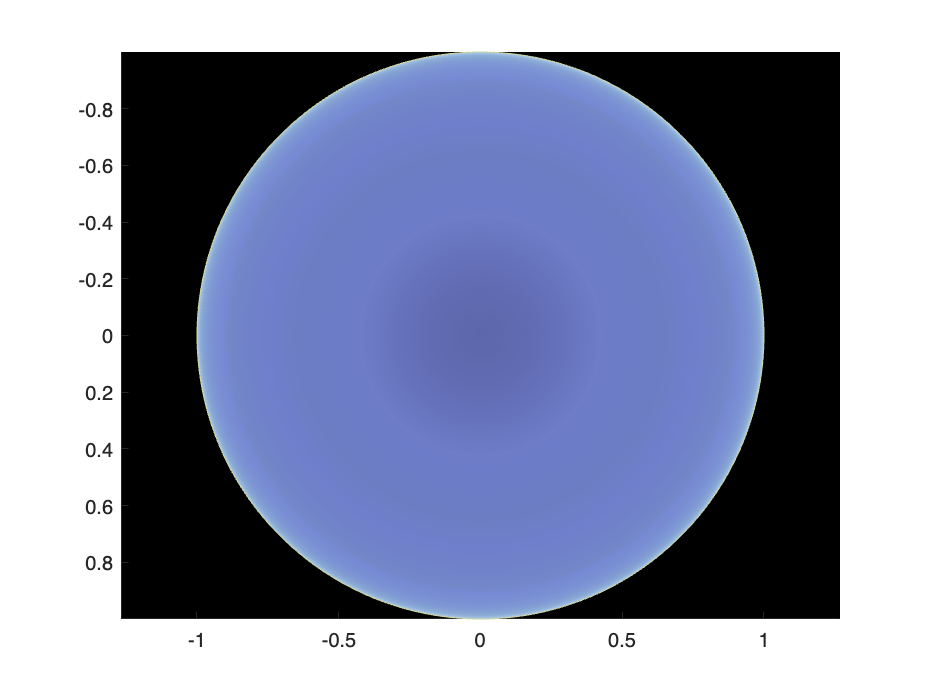

sunDir = [cosd(90),0,sind(90)];
viewPos = [0,0,1+1e-5];
theta = linspace(0, 2*pi, 512);
phi = linspace(pi/2, 0, 512);
[T, P]=meshgrid(theta, phi);
I = [];

viewDir = [];
viewDir(:,1) = cos(T(:)).*cos(P(:));
viewDir(:,2) = sin(T(:)).*cos(P(:));
viewDir(:,3) = sin(P(:));

% If in space, map viewPos to atmosphere top
for i = 1:max(size(viewDir,1),size(viewPos,1))
end

% Process indata
r = norm(viewPos) + 0.*T(:);
mu = dot(viewPos+ 0*T(:),viewDir,2)./vecnorm(viewPos,2,2);
mu_s = dot(viewPos+ 0*T(:), sunDir + 0*T(:),2)./vecnorm(viewPos,2,2);
nu = dot(viewDir, sunDir + 0*T(:),2);

% Compute scattering
Ivp = GetScattering(r, mu, mu_s, nu, kLambda, kSolarIrradiance, atmosphere);

% Process outdata
for l = 1:numel(kLambda)
    I(:,:,l) = reshape(Ivp(:,l), size(T,1),[]);
end

% Irradiance to RGB
c_bar = Lambda2RGB(kLambda*1e3);
C = 0*I(:,:,1:3);
dlambda = diff([350 kLambda.'*1e3]);
for l = 1:numel(kLambda)
    C(:,:,1) = C(:,:,1) + I(:,:,l).*c_bar(l,1)*dlambda(l);
    C(:,:,2) = C(:,:,2) + I(:,:,l).*c_bar(l,2)*dlambda(l);
    C(:,:,3) = C(:,:,3) + I(:,:,l).*c_bar(l,3)*dlambda(l);
end

clf,figure
[T1,R1] = pol2cart(T, cos(P));
warp(T1,R1,0*T1,tonemapfarbman(max(C,0),'Exposure',0.5)),view(2),shading interp,view(2),axis equal,set(gca,'color','k')

%image(tonemapfarbman(max(C,0),'Exposure',0.5)),shading interp

function out = F_Depth(F_Rho, viewPos, viewDir, collisionSpheres, rCollisionSpheres)
[intersections, hits_ground] = IntersectRayAtmosphere(viewPos, ...
                                    viewDir, ...
                                    collisionSpheres,...
                                    rCollisionSpheres); 
if isempty(intersections)
    out = 0;
else
if norm(viewPos - collisionSpheres(1,:)) <= rCollisionSpheres(end)
    intersections = [viewPos;intersections];
end
cc = 0.5*(intersections(1:end-1,:) + intersections(2:end,:));
pp = vecnorm(intersections(1:end-1,:) - intersections(2:end,:),2,2);
hh = vecnorm(cc,2,2) - rCollisionSpheres(1);
hh = max(hh,0);
rho = F_Rho(hh);
out = sum(pp .* rho);
end

end

function out = F_Transmittence(FI_Depth, beta, F_Rho, r, mu, mu_s, nu, collisionSpheres, rCollisionSpheres)
viewPos = [0,0,r];
viewDir = [sqrt(1-mu.^2),0,mu];
Rg = rCollisionSpheres(1);
Rt = rCollisionSpheres(end);

[intersections, hits_ground] = IntersectRayAtmosphere(viewPos, ...
                                    viewDir, ...
                                    collisionSpheres,...
                                    rCollisionSpheres); 
out = 0*beta;
absorb = 0;
if isempty(intersections), return; end

if norm(viewPos - collisionSpheres(1,:)) <= rCollisionSpheres(end)
    intersections = [viewPos;intersections];
else
    viewPos = intersections(1,:);
    intersections = intersections(2:end,:);
end

[u_r, u_mu] = RMuEncoding(atmosphere, r, mu);

xc = 0.5*(intersections(1:end-1,:) + intersections(2:end,:));
ds = vecnorm(intersections(1:end-1,:) - intersections(2:end,:),2,2);
heights = vecnorm(xc,2,2) - rCollisionSpheres(1);

transmittence = 0.*beta;
for i = 1:numel(ds)
    point = intersections(i+1,:);
    d_i = norm(point - viewPos);
    r_d = sqrt(d_i .* d_i + 2.0 * r .* mu .* d_i + r .* r);
    mu_d = ((r .* mu + d_i) ./ r_d);
    mu_s_d = (r * mu_s + d_i * nu) ./ r_d;

    in_shadow = RayIntersectsGround(r_d, mu_s_d, Rg);
    if in_shadow,continue,end

    [u_rd, u_mu_sd] = RMuEncoding(atmosphere, r_d, mu_s_d);
    [~, u_mu_d] = RMuEncoding(atmosphere, r_d, mu_d);
    
    t_ppc = FI_Depth(u_rd, u_mu_sd);
    if hits_ground
        t_ppa = FI_Depth(u_rd, -u_mu_d)-FI_Depth(u_r, -u_mu);
    else
        t_ppa = FI_Depth(u_r, u_mu) - FI_Depth(u_rd, u_mu_d);
    end
    extinction = (t_ppa + t_ppc) .* (beta + absorb);
    tr = ds(i) * F_Rho(heights(i))*exp(-extinction);
    transmittence = transmittence + tr;
end
out = transmittence;
end

function out = GetScattering(r, mu, mu_s, nu, lambda, solarIrradiance, atmosphere)
[u_r, u_mu, u_mus, u_nu] = RMuMusNuEncoding(atmosphere, r, mu, mu_s, nu);
transmittence = squeeze(atmosphere.cachedTransmittence(u_r, u_mu, u_mus, u_nu));
transmittence(~isfinite(transmittence)) = 0;
for l = 1:numel(lambda)
    out(:,l) = solarIrradiance(l) .* atmosphere.rayleigh ./ lambda(l).^4 .* atmosphere.rayleighPhaseFunction(nu) .* transmittence(:,l);
end
end
